## Extraindo os parâmetros do motor:

% % Omega - velocidade
% % Theta - posição
% % Entrada
% 
% %%% Especificando o tempo - eixo x 
% 
% tempo = Entrada.time; % *Entrada.time == Omega.time
% 
% Omega = Omega.signals.values
% Entrada_ = Entrada.signals.values
% 
% %%% Visualizando o sinal:
% 
% figure(1)
% 
% subplot(3,1,1)
% plot(tempo,Entrada_);
% title('Entrada do sistema');
% ylabel('Tensão em Volts');
% xlabel('Tempo em segundos');
% grid;
% 
% subplot(3,1,2)
% plot(tempo,Omega);
% title('Rotação');
% ylabel('Tensão em Volts');
% xlabel('Tempo em segundos');
% grid;
% 
% figure()
% 
% plot(tempo,Omega);
% title('Rotação');
% ylabel('Tensão em Volts');
% xlabel('Tempo em segundos');
% grid;
% 
% set(findall(gcf,'Type','line'),'LineWidth',2);
% set(gca,'FontSize',21,'LineWidth',1.5);
% 
% %%% Determinando a função de transferência (Assumindo Modelo de primeira ordem)
% 
% Gp = tf(1,[1,1])
% 
% ym = lsim(Gp,Entrada_,tempo);            % saída do modelo para a mesma entrada
% figure(2)
% plot(tempo,Entrada_, tempo,Omega, tempo,ym, 'LineWidth',2);
% axis([0 5 -5 5]);
% title('Comparação entre modelo e dados');
% ylabel('Tensão em Volts');
% xlabel('Tempo em segundos');
% grid;
% 
% %%% Ajustando os parâmetros T e K
% 
% x0 = [1 1];         % condição inicial Km = 1 e pm = 1
% 
% X = fminsearch(@(x) ErroQuadratico(x,Entrada,Omega,tempo') , x0)
% 
% %%% Verificando os resultados:
% 
% Gp = tf(X(1), [1 X(2)])         % função de transferência do modelo Km = X(1) e pm = X(2)
% 
% 
% ym = lsim(Gp,Entrada_,tempo);    % saída do modelo
% figure(2)
% plot(tempo,Entrada_, tempo,Omega, tempo,ym, 'LineWidth',2);
% axis([0 5 -5 5]);
% title('Comparação entre modelo e dados');
% ylabel('Tensão em Volts');
% xlabel('Tempo em segundos');
% grid;

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%% Análise do Sistema original em malha aberta

% Reescrevendo a função de transferência do motor:

% Kmotor = X(1)
% Tmotor = X(2)

Kmotor = 130

Kmotor = 130

Tmotor = 6

Tmotor = 6


Gmotor  = tf(Kmotor, [1 Tmotor])

Gmotor =
 
   130
  -----
  s + 6
 
Continuous-time transfer function.



## Análise Inicial - Apenas Motor (integrando para obter posição)

%%% Definindo o integrador

Integrador = tf(1, [1 0])

Integrador =
 
  1
  -
  s
 
Continuous-time transfer function.




%%% Analisando em malha fechada -> Integrando para posição

Gmf_mot_solo = feedback(Gmotor,1);
Gmf_mot_solo = Gmf_mot_solo * Integrador

Gmf_mot_solo =
 
      130
  -----------
  s^2 + 136 s
 
Continuous-time transfer function.



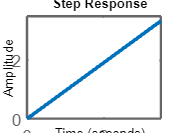


%%% Visualização

figure(1)
step(Gmf_mot_solo);
set(findall(gcf,'Type','line'),'LineWidth',3);
set(gca,'FontSize',14,'LineWidth',2);


%%% Polos originais - Motor sozinho em malha fechada

Dmf_mot_solo = [1 Tmotor 0];
Nmf_mot = Kmotor;

pmf_mot_solo = roots(Dmf_mot_solo)

pmf_mot_solo =      0
    -6


## Determinando o Polo Desejado

% Definição do Controlador como Função de Transferência
%              
%              s + z     sK + zK
% Gcont = K * ------- = ------------
%              s + p      s + p
%

% Parâmetros de Projeto
Mp = 25;        % Sobressinal Máximo (%)
tp = 0.1;       % Tempo de Pico (s)
ts = 0.1;       % Tempo de Assentamento inicial 

% Determinando o Amortecimento, Frequência Natural e Amortecida do sistema

zeta = -log(Mp/100) / sqrt(pi^2 + (log(Mp/100))^2) % Extraído da definição de Mp

zeta = 0.4037


omega_n = pi / (tp * sqrt(1 - zeta^2))

omega_n = 34.3386


omega_d = (sqrt(1 - zeta^2))* omega_n

omega_d = 31.4159


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

% Determinando os polos desejados { Pd = -(zeta*omega_n) +- j*omega_d }

sigma = -(zeta*omega_n)

sigma = -13.8629

j_omega_positivo = j*omega_d    % Trabalhando apenas na parte y > 0 do gráfico

j_omega_positivo = 0.0000 + 31.4159i



%%% Polos conhecidos até este momento:

pmf_mot_solo    % Relembrando

pmf_mot_solo =      0
    -6



%
% * Polos do Motor = (0 | -5.6) (depende dos resultador acima)
%
% * Polo Desejado = 
%

## Análise Geométrica

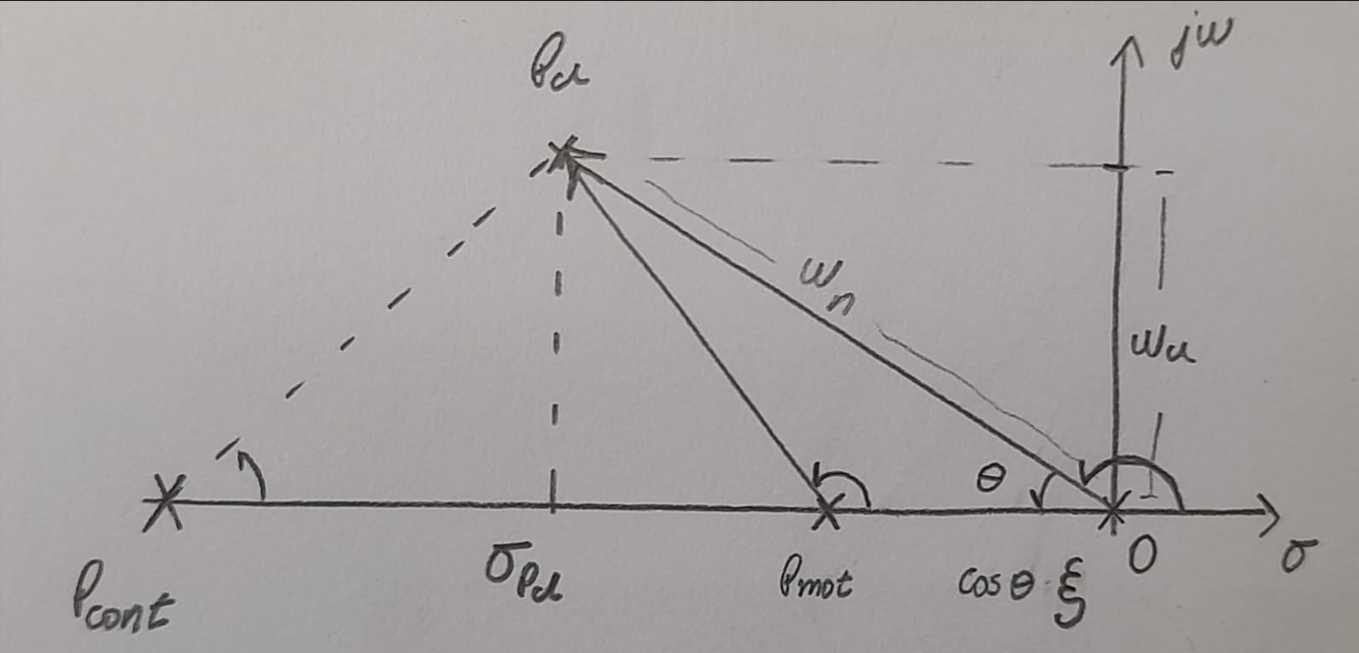

% Analisando o Angulo Theta_Zero {Origem <) Pd}

theta_amort_deg = rad2deg(acos(zeta))

theta_amort_deg = 66.1895


% Fase do polo da origem (complemento do angulo de amortecimento)
theta_zero_deg = 180 - theta_amort_deg

theta_zero_deg = 113.8105


% Análise do Polo vindo do motor isolado (Vetor Polo_mot -> P_desejado)

dist_horiz_pd_pmot = abs(pmf_mot_solo(2) - sigma)  % Distancia horizontal entre o polo

dist_horiz_pd_pmot = 7.8629

                                                   % do motor e o polo desejado

ro_pmot = sqrt((omega_d^2) + dist_horiz_pd_pmot^2)

ro_pmot = 32.3850

theta_pmot = 180 - rad2deg(atan(omega_d/ro_pmot))

theta_pmot = 135.8702

## Determinando os parâmetros do Controlador

Neste ponto, será considerada a relação **Gcont(s)*Gmot(s) = -1** interpretada na forma polar como **Gcont(s)*Gmot(s) * Integrador(s) = 1 **∠ 180°.

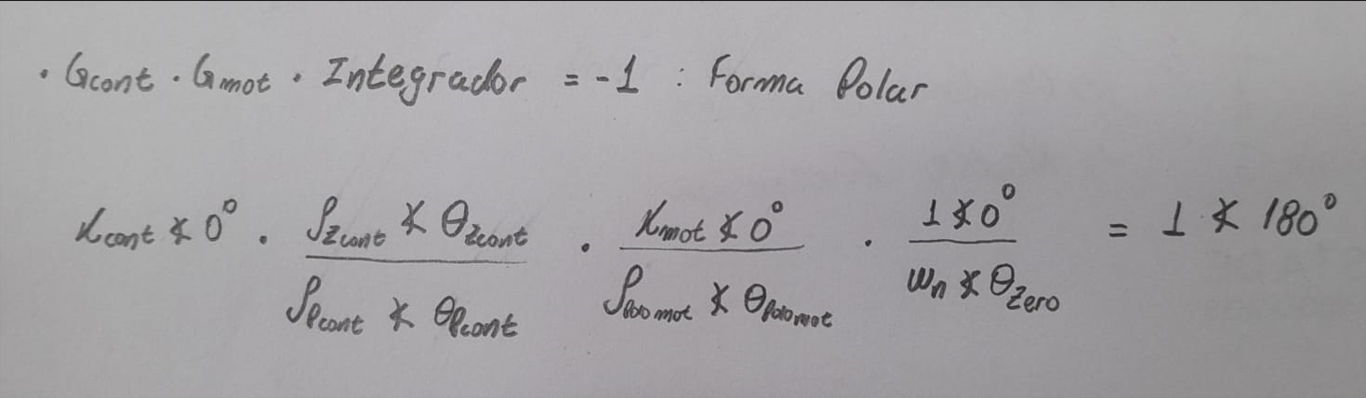

Desta relação pode-se extrair 2 outras Expressões:

**Π** Módulos (*Gcont(s)*Gmot(s)*Integrador(s)*) = 1

Σ Fases (*Gcont(s)*Gmot(s)*Integrador(s)*) = 180°

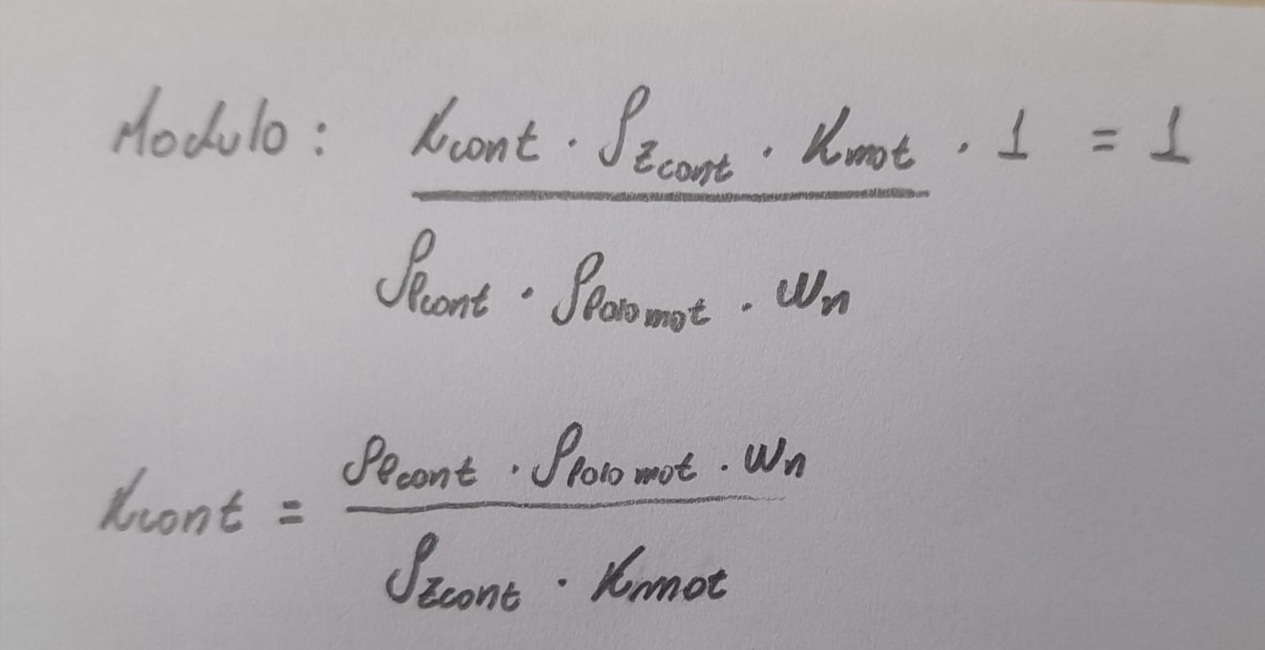

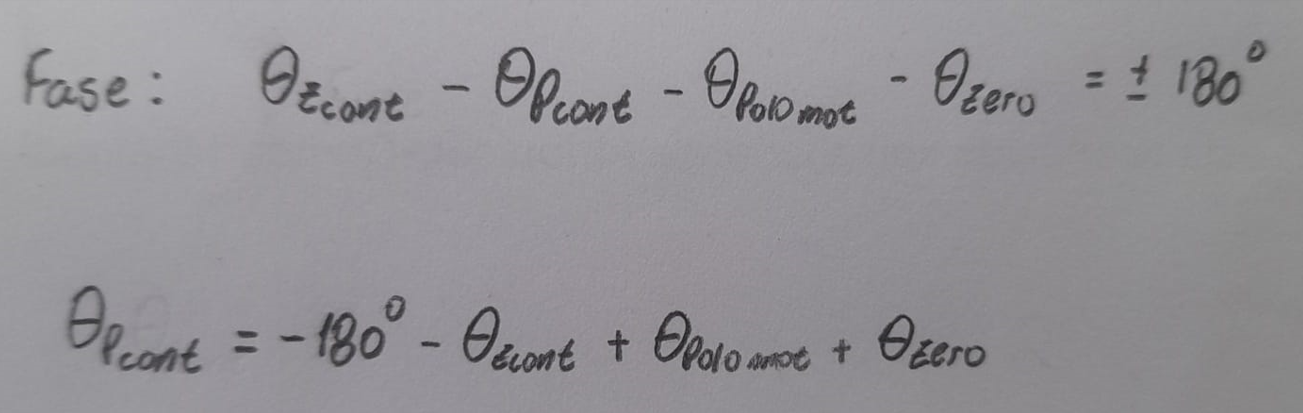

% Determinando theta_Pcont a partir da relação de fase:

% Neste ponto deve-se arbitrar um dos parâmetros explicitados nas
% relações acima. Opta-se por arbitrar a posição do Zero do Controlador
% como Zcont = ro_Zcont ∠ theta_Zcont = omega_d ∠ 90° (o zero a ser posicionado
% a projeção ortogonal do Polo desejado no eixo real sigma)

theta_Zcont = 90;
theta_pmot

theta_pmot = 135.8702

theta_zero_deg

theta_zero_deg = 113.8105


theta_Pcont = theta_Zcont - (-180 + theta_pmot + theta_zero_deg)

theta_Pcont = 20.3193


% Determinando o valor de P (Gráfico):

dist_horiz_pd_Pcont = omega_d/tan(deg2rad(theta_Pcont))

dist_horiz_pd_Pcont = 84.8403


Pcont = abs(sigma)  + dist_horiz_pd_Pcont

Pcont = 98.7032


ro_Pcont = sqrt(Pcont^2 + omega_d^2)

ro_Pcont = 103.5823

 
% Determinando Kcont a partir da rekação de módeulos:

ro_Zcont = omega_d; % Pela condição arbitrada anteriormente

Kcont = (ro_Pcont * ro_pmot * omega_n)/(ro_Zcont * Kmotor)

Kcont = 28.2045